# MODELO ARX PRUEBA ESCALÓN

## IDENTIFICACION DE PROCESOS USANDO MINIMOS CUADRADOS

clear all
close all

Datos=xlsread('Datos_Escalon - Copy.xlsx');
Datos(any(isnan(datos), 2), :) = [];
t=Datos(:,1);
U=Datos(:,2);
Y=Datos(:,4);

subplot(2,1,1)
plot(t,U,'* k','MarkerSize',4)
ylabel('Entrada')
grid on
subplot(2,1,2)
plot(t,Y,'o b','MarkerSize',4)
ylabel('Salida')
xlabel('Tiempo')
hold on
grid on

% Seleccionando na=3, nb=3, d=1
s=length(Y);

X=[-[0;Y(1:s-1)],-[0;0;Y(1:s-2)],-[0;0;0;Y(1:s-3)],[0;U(1:s-1)],[0;0;U(1:s-2)],[0;0;0;U(1:s-3)],[0;0;0;0;U(1:s-4)]];

%Matriz de covarianzas
Q=X'*X

Q = 1.0e+04 *

    2.9678    2.8089    2.6401   -0.4430   -0.4430   -0.4317   -0.4128
    2.8089    2.8257    2.6194   -0.4203   -0.4203   -0.4203   -0.4090
    2.6401    2.6194    2.5730   -0.3902   -0.3902   -0.3902   -0.3902
   -0.4430   -0.4203   -0.3902    0.0720    0.0684    0.0648    0.0612
   -0.4430   -0.4203   -0.3902    0.0684    0.0684    0.0648    0.0612
   -0.4317   -0.4203   -0.3902    0.0648    0.0648    0.0648    0.0612
   -0.4128   -0.4090   -0.3902    0.0612    0.0612    0.0612    0.0612



%Vector de parámetros
Theta=inv(Q)*X'*Y

Theta =     0.3205
    0.3732
   -0.1128
    3.1416
    3.1011
    2.3673
    2.0106



% Tu periodo de muestreo
T = 0.1;

z=tf('z',T);
Gpm=((Theta(4)*z^3+Theta(5)*z^2+Theta(6)*z+Theta(7))/(z^3+Theta(1)*z^2+Theta(2)*z+Theta(3)))*(z^(-1))

Gpm =
 
  3.142 z^3 + 3.101 z^2 + 2.367 z + 2.011
  ----------------------------------------
  z^4 + 0.3205 z^3 + 0.3732 z^2 - 0.1128 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%step(Gpm,'r--',2)
grid on
%Ym=step(Gpm,14);
Ym = lsim(Gpm,U,t)

Ym =          0
   18.8496
   31.4159
   34.5575
   43.0500
   40.5732
   38.5515
   41.0815
   40.7460
   39.6812


plot(t,Ym)

%Validación del modelo
Sy=sum((Y-mean(Y)).^2)

Sy = 2.4965e+03

Sr=sum((Y-Ym).^2)

Sr = 619.6076

R2=(Sy-Sr)/Sy

R2 = 0.7518

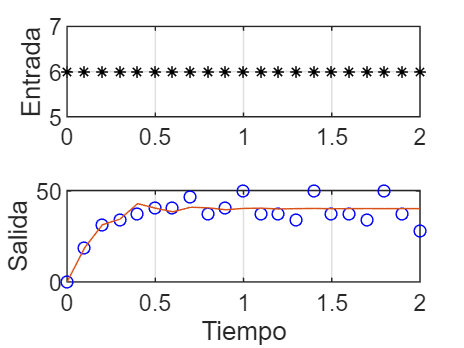

hold off



% Convertir Gpm_z a una función de transferencia en s usando la transformación bilineal
Gpm_s = d2c(Gpm, 'tustin');

% Ahora Gpm_s es tu función de transferencia en s
figure;
step(Gpm);
hold on
step(Gpm_s);


deltaY = max(Ym) - Ym(1);
Kp = deltaY/6.5;
inicioSubida = find(Ym > Ym(1) + 0.05 * deltaY, 1, 'first'); % Encuentra el inicio de la subida
theta = 0.05;
tiempo63porciento = find(Ym >= Ym(1) + 0.632 * deltaY, 1, 'first');
tau = t(tiempo63porciento) - theta;
% Ahora puedes definir tu función de transferencia en s
s = tf('s');
Gpm_s = Kp * exp(-theta * s) / (tau * s + 1)

Gpm_s =
 
                   6.623
  exp(-0.05*s) * ----------
                 0.15 s + 1
 
Continuous-time transfer function.



step(Gpm_s);

# MODELO ARX PRUEBA PRBS

## IDENTIFICACION DE PROCESOS USANDO MINIMOS CUADRADOS

Datos_prbs=xlsread('Datos_PRBS.xlsx');

t_prbs=Datos_prbs(:,1);
U_prbs=Datos_prbs(:,2);
Y_prbs=Datos_prbs(:,4);

subplot(2,1,1)
plot(t_prbs,U_prbs,'* k','MarkerSize',4)
ylabel('Entrada')
grid on
subplot(2,1,2)
plot(t_prbs,Y_prbs,'o b','MarkerSize',4)
ylabel('Salida')
xlabel('Tiempo')
hold on
grid on

% Seleccionando na=3, nb=3, d=1
s_prbs=length(Y_prbs);

X_prbs=[-[0;Y_prbs(1:s_prbs-1)],-[0;0;Y_prbs(1:s_prbs-2)],-[0;0;0;Y_prbs(1:s_prbs-3)],[0;U_prbs(1:s_prbs-1)],[0;0;U_prbs(1:s_prbs-2)],[0;0;0;U_prbs(1:s_prbs-3)],[0;0;0;0;U_prbs(1:s_prbs-4)]];

%Matriz de covarianzas
Q_prbs=X_prbs'*X_prbs

Q_prbs = 1.0e+04 *

    9.5025    9.0327    8.4148   -1.3647   -1.3892   -1.3270   -1.2158
    9.0327    9.5025    9.0327   -1.2535   -1.3647   -1.3892   -1.3270
    8.4148    9.0327    9.5025   -1.1347   -1.2535   -1.3647   -1.3892
   -1.3647   -1.2535   -1.1347    0.2160    0.1980    0.1800    0.1620
   -1.3892   -1.3647   -1.2535    0.1980    0.2160    0.1980    0.1800
   -1.3270   -1.3892   -1.3647    0.1800    0.1980    0.2160    0.1980
   -1.2158   -1.3270   -1.3892    0.1620    0.1800    0.1980    0.2160



%Vector de parámetros
Theta_prbs=inv(Q_prbs)*X_prbs'*Y_prbs

Theta_prbs =    -0.1364
    0.0122
   -0.0156
    4.6421
    1.0590
    0.1204
   -0.2058



z=tf('z',0.1);

Gpm_prbs=((Theta_prbs(4)*z^3+Theta_prbs(5)*z^2+Theta_prbs(6)*z+Theta_prbs(7))/(z^3+Theta_prbs(1)*z^2+Theta_prbs(2)*z+Theta_prbs(3)))*(z^(-1))

Gpm_prbs =
 
  4.642 z^3 + 1.059 z^2 + 0.1204 z - 0.2058
  ------------------------------------------
  z^4 - 0.1364 z^3 + 0.01225 z^2 - 0.01557 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



%step(Gpm,'r--',12)
grid on
Ym_prbs=lsim(Gpm_prbs, U_prbs, t_prbs)

Ym_prbs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


plot(t_prbs,Ym_prbs)
%Ym=step(Gpm,12);

%Validación del modelo
Sy_prbs=sum((Y_prbs-mean(Y_prbs)).^2)

Sy_prbs = 4.4119e+04

Sr_prbs=sum((Y_prbs-Ym_prbs).^2)

Sr_prbs = 4.8740e+03

R2_prbs=(Sy_prbs-Sr_prbs)/Sy_prbs

R2_prbs = 0.8895

hold off
close all

% Convertir Gpm_z a una función de transferencia en s usando la transformación bilineal
Gpm_s = d2c(Gpm, 'tustin');

% Ahora Gpm_s es tu función de transferencia en s
figure;
step(Gpm);
hold on
step(Gpm_s);

### **CRUZADOS**

% Step Response del modelo PRBS
figure; % Crear una nueva figura
step(Gpm_prbs,'b-'); % Añade 'LineWidth',2 para hacer la línea más gruesa
set(findall(gcf,'type','line'),'linewidth',2);
title('Step Response del modelo PRBS');
ylabel('Entrada');
xlabel('Tiempo');
grid on;
legend('Modelo PRBS'); % Añade la leyenda


% Step Response del modelo Escalon
figure; % Crear una nueva figura
step(Gpm,'r-'); % Añade 'LineWidth',2 para hacer la línea más gruesa
set(findall(gcf,'type','line'),'linewidth',2);
title('Step Response del modelo Escalon');
ylabel('Entrada');
xlabel('Tiempo');
grid on;
legend('Modelo Escalón'); % Añade la leyenda


% PRBS Response del modelo Escalon
figure; % Crear una nueva figura
lsim(Gpm,U_prbs,t_prbs,'r-'); % Añade 'LineWidth',2 para hacer la línea más gruesa
set(findall(gcf,'type','line'),'linewidth',2);
title('PRBS Response del modelo Escalon');
ylabel('Entrada');
xlabel('Tiempo');
grid on;
legend('Modelo Escalón con Entrada PRBS'); % Añade la leyenda


% PRBS Response del modelo PRBS
figure; % Crear una nueva figura
lsim(Gpm_prbs,U_prbs,t_prbs,'b-'); % Añade 'LineWidth',2 para hacer la línea más gruesa
set(findall(gcf,'type','line'),'linewidth',2);
title('PRBS Response del modelo PRBS');
ylabel('Entrada');
xlabel('Tiempo');
grid on;
legend('Modelo PRBS con Entrada PRBS'); % Añade la leyenda